# SHORT PROJECT

## Learn descriptors from reference images

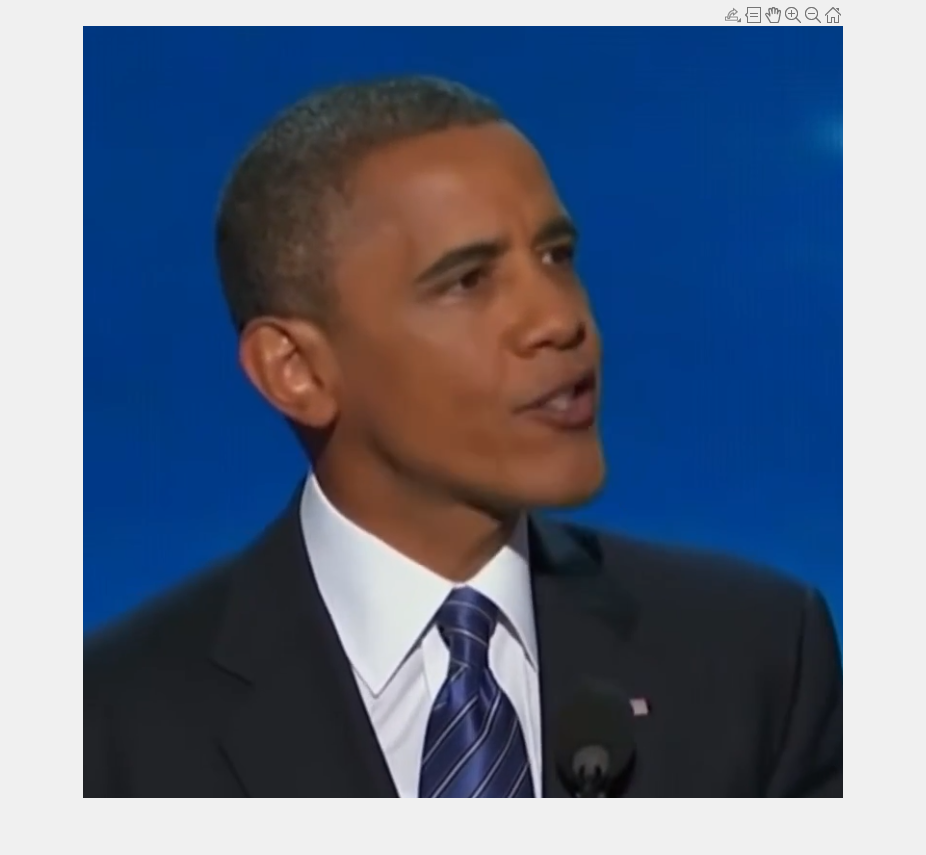

clear
% Reference image
referenceImagesDir = uigetdir(pwd, 'Select a folder');
referenceImages = dir(fullfile(referenceImagesDir, '*.png'));

% Storage for the reference descriptors and locations
referenceDescriptorsList = cell(length(referenceImages), 1);
referencePointsList = cell(length(referenceImages), 1);

% size of neighbour pixels that will be taken into account in the
% descriptor features
sizeOfFeatures = 20;

for i = 1:length(referenceImages)

    referenceImage = imread(strcat(referenceImagesDir, '\', referenceImages(i).name));
    imshow(referenceImage);
    % Select manually the key points
    [x, y] = ginput;
    selectedPoints = [x, y];

    % Extract features manually
    referenceDescriptors = extractManualFeatures(referenceImage, selectedPoints, sizeOfFeatures);
    
    referenceDescriptorsList{i} = referenceDescriptors;
    referencePointsList{i} = selectedPoints;

end

## Compare different images

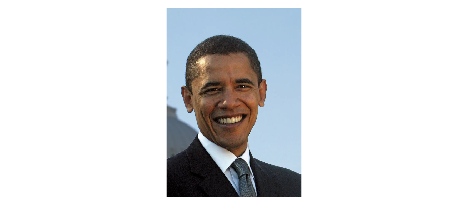

newImage = imread("imageComparisons\BarackObamaComparison.PNG");
imshow(newImage)

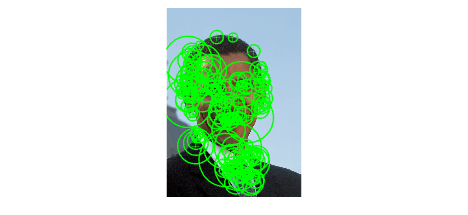


% Extract possible interest points by using surf (other methods
% have been tried and this seems the optimal one)
surfPointsVideo = detectSURFFeatures(rgb2gray(newImage));

imshow(newImage);
hold on;
plot(surfPointsVideo);

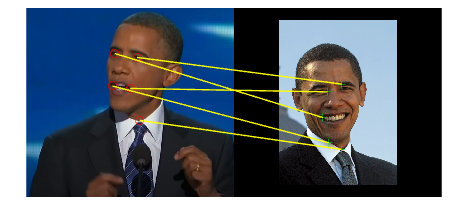


surfPoints = surfPointsVideo.Location;

% we extract the descriptors from this interest points
newImageDescriptors = extractManualFeatures(newImage, surfPoints, sizeOfFeatures);
 
bestMatchCount = 0;
bestReferenceImage = [];
bestMatchedRefPoints = [];
bestMatchednewImagePoints = [];

% For each reference we calculate its matching and if it has the
% most matches we store it
for i = 1:length(referenceDescriptorsList)

    referenceImage = imread(strcat(referenceImagesDir, '\', referenceImages(i).name));

    referenceDescriptors = referenceDescriptorsList{i};
    referencePoints = referencePointsList{i};
        
    % Manual matching
    [matchedRefPoints, matchedNewImagePoints] = manualMatchFeatures(referenceDescriptors, referencePoints, newImageDescriptors, surfPoints, 1.9);

    % Number of matches
    matchCount = size(matchedRefPoints, 1);
        
    % Update results
    if matchCount > bestMatchCount
        bestMatchCount = matchCount;
        bestReferenceImage = referenceImage;
        bestMatchedRefPoints = matchedRefPoints;
        bestMatchedNewImagePoints = matchedNewImagePoints;
    end

end

% Visualizar las coincidencias con la mejor imagen de referencia encontrada
if ~isempty(bestReferenceImage)
    figure;
    showMatchedFeatures(bestReferenceImage, newImage, bestMatchedRefPoints, bestMatchedNewImagePoints, 'montage');
end

## Play video with matching features

% Read a video frame and run the face detector.
videoReader = VideoReader('PATH\NameOfInputVideo.mp4');
videoFrame = readFrame(videoReader);
videoPlayer = vision.VideoPlayer();
frameRate = videoReader.FrameRate;

resultingVideo = VideoWriter('PATH\NameOfOutputVideo.mp4', 'MPEG-4');

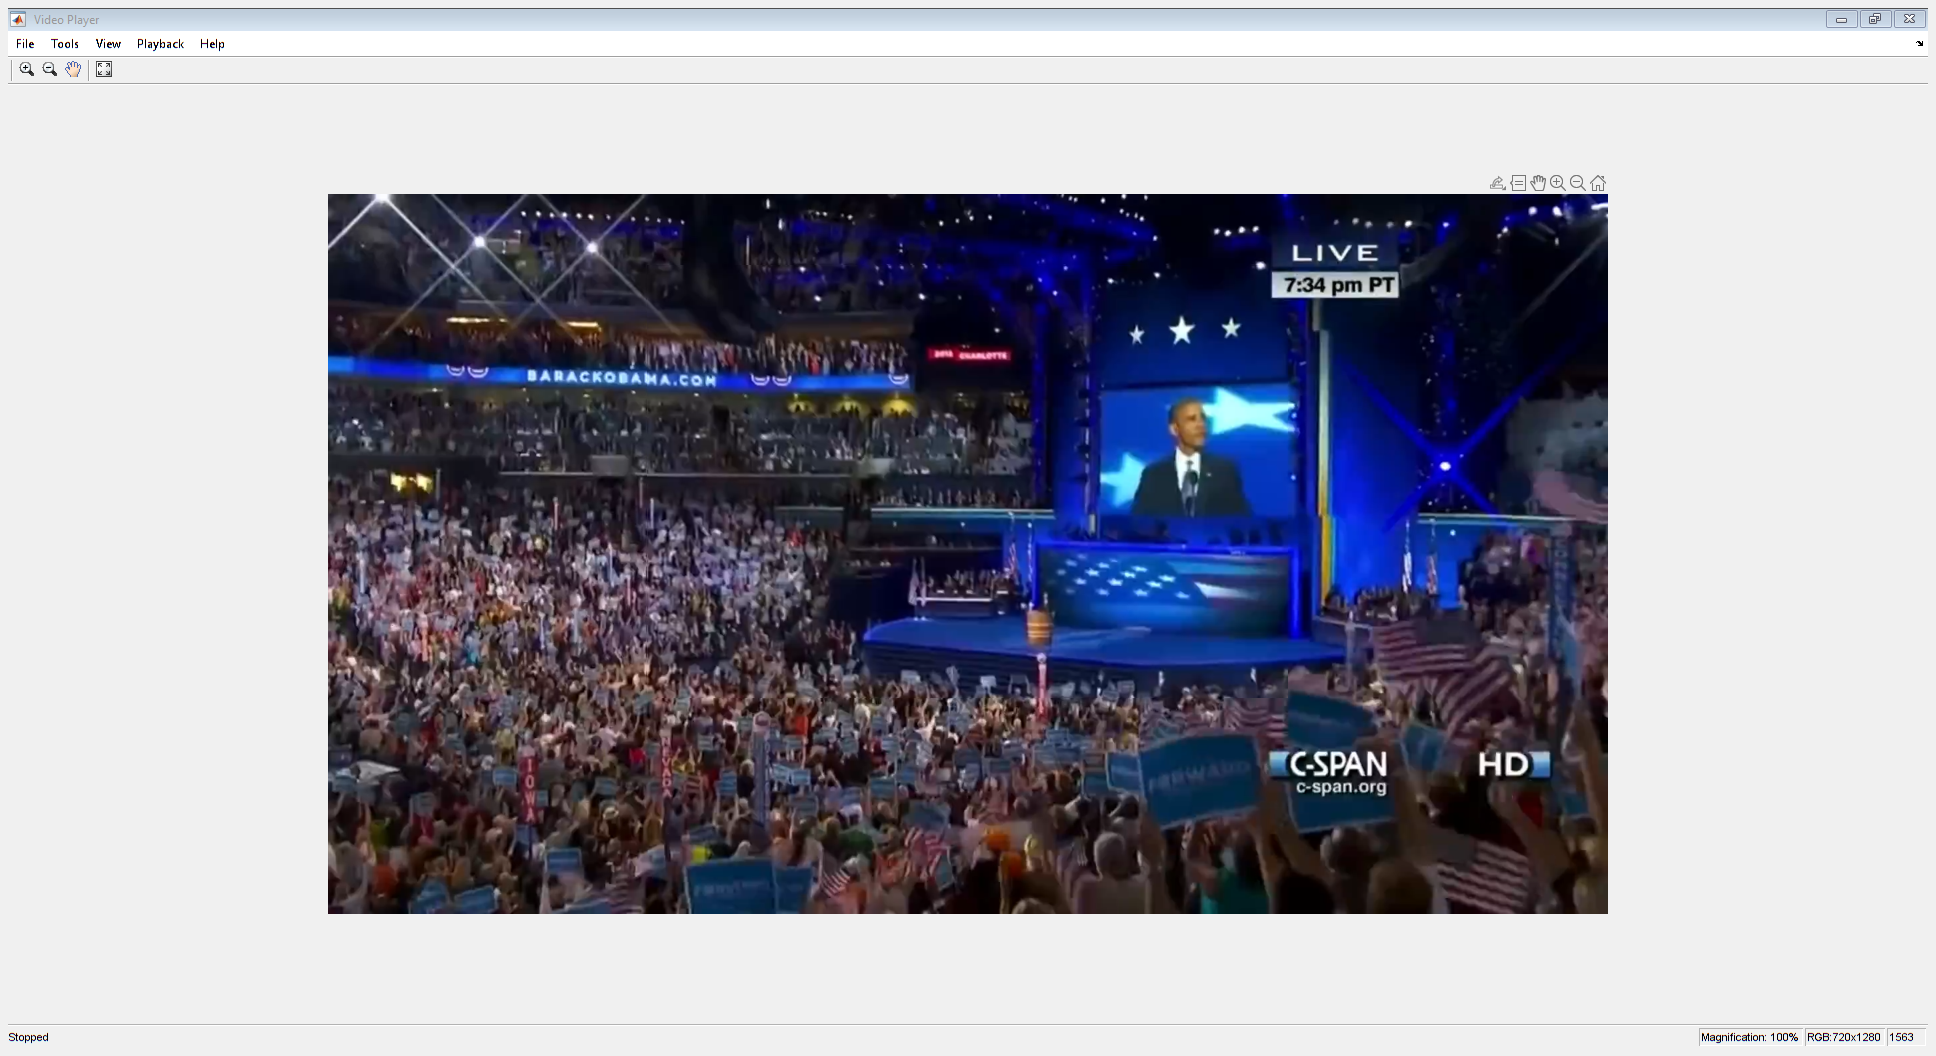

resultingVideo.FrameRate = videoReader.FrameRate;
open(resultingVideo);

%we calculate each x frames as it is not needed to do each one to get a
%good result and it improves efficiency
frequencyOfMatching = 3;
frames = 0;

% We erase some of the borders of the video to improve efficiency, as the
% face will not be there
resize = 1.5;
videoFrame = imresize(videoFrame, 1/resize);

[f, c, ~] = size(videoFrame);

borderWidth = c/4;
borderHeight = f/10;
rectLength = c-borderWidth*2;
rectHeight = f-borderHeight*4;

croppedBorder = [borderWidth borderHeight rectLength rectHeight]; 

% each iteration is a frame
while hasFrame(videoReader)
    frameStart = tic;

    % get the next frame
    videoFramePre = videoFrame;
    videoFrame = readFrame(videoReader);

    videoFrame = imresize(videoFrame, 1/resize);

    % Show rectangle 
    %annotatedFrame = insertShape(videoFrame, 'Rectangle', croppedBorder, 'Color', 'yellow', 'LineWidth', 10);    
    %imshow(annotatedFrame)
    
    % each x frames we do the matching again
    if mod(frames, frequencyOfMatching) == 0

        borderlessFrame = imcrop(videoFrame, croppedBorder);

        % Extract possible interest points by using surf (other methods
        % have been tried and this seems the optimal one)
        surfPointsVideo = detectSURFFeatures(rgb2gray(borderlessFrame));
        surfPoints = surfPointsVideo.Location;

        % we extract the descriptors from this interest points
        videoFrameDescriptors = extractManualFeatures(borderlessFrame, surfPoints, sizeOfFeatures);
 
        bestMatchCount = 0;
        bestMatchedVideoFramePoints = [];

        % For each reference we calculate its matching and if it has the
        % most matches we store it
        for i = 1:length(referenceDescriptorsList)

            referenceDescriptors = referenceDescriptorsList{i};
            referencePoints = referencePointsList{i};
        
            % Manual matching
            [matchedRefPoints, matchedVideFramePoints] = manualMatchFeatures(referenceDescriptors, referencePoints, videoFrameDescriptors, surfPoints, 1.25);

            % Number of matches
            matchCount = size(matchedRefPoints, 1);
        
            % Update results
            if matchCount > bestMatchCount
                bestMatchCount = matchCount;
                bestMatchedVideoFramePoints = matchedVideFramePoints;
            end

        end
        
    end

    % Show matches with a marker
    if ~isempty(bestMatchedVideoFramePoints)
        borderlessFrame = insertMarker(borderlessFrame, bestMatchedVideoFramePoints, 'o', 'Color', 'green');
    end

    videoFrame(borderHeight:borderHeight+rectHeight, borderWidth:borderWidth+rectLength, :) = borderlessFrame;

    writeVideo(resultingVideo, videoFrame);
    step(videoPlayer, videoFrame);

    %end of frame
    frames = frames + 1;
    
    %control of speed so it runs at most the frame rate of the video
    frameDuration = toc(frameStart);
    stopVideo = (1/frameRate) - frameDuration;
    if stopVideo > 0
        pause(stopVideo);
    end
end

% Clear videos
close(resultingVideo);
release(videoPlayer);

## Extract descriptors manually from interest points

function allDescriptors = extractManualFeatures(image, points, neighboursSize)   

    grayImage = rgb2gray(image);

    % Start descriptor arrays
    %grayScaleDescriptors = [];
    gradientDescriptors = [];
    hsvHistogramDescriptors = [];
    lbpDescriptors = [];

    % neighbour size each side
    halfSize = floor(neighboursSize/2);
    [f, c] = size(image);
    
    % for each point we get its descriptors
    for i = 1:size(points, 1)

        x = round(points(i, 1));
        y = round(points(i, 2));
        
        % dont take into account pixels off the image
        if halfSize < y && f - halfSize >= y && halfSize < x && c - halfSize >= x

            %region evaluated
            neighbours = image(y-halfSize:y+halfSize, x-halfSize:x+halfSize, :);
            grayNeighbours = grayImage(y-halfSize:y+halfSize, x-halfSize:x+halfSize, :);
            
            %DESCRIPTORS:

            % Color histogram HSV normalized.
            hsvHistogramDescriptor = [];
            neighboursHSV = rgb2hsv(neighbours);
            for chanel = 1:3
                histHSV = imhist(neighboursHSV(:, :, chanel), 36);
                histHSV = histHSV / sum(histHSV);
                hsvHistogramDescriptor = [hsvHistogramDescriptor; histHSV];
            end
            hsvHistogramDescriptor = hsvHistogramDescriptor(:)';
    

            % gray scale normalized (not working properly as HSV seems like
            % a strict upgrade
            %grayScaleDescriptor = double(grayNeighbours(:))';
            %grayScaleDescriptor = grayScaleDescriptor / norm(grayScaleDescriptor);
            

            % Gradient normalized
            [Gx, Gy] = imgradientxy(grayNeighbours);
            gradientDescriptor = [Gx(:)', Gy(:)'];
            gradientDescriptor = gradientDescriptor / norm(gradientDescriptor);
            
            % LBP (not done manually) for textures
            lbpDescriptor = extractLBPFeatures(grayNeighbours);

            %grayScaleDescriptors = [grayScaleDescriptors; grayScaleDescriptor];
            gradientDescriptors = [gradientDescriptors; gradientDescriptor];
            hsvHistogramDescriptors = [hsvHistogramDescriptors; hsvHistogramDescriptor];
            lbpDescriptors = [lbpDescriptors; lbpDescriptor];
        end

    end

    allDescriptors = [gradientDescriptors, hsvHistogramDescriptors, lbpDescriptors];

end

## Manual matching of features by distance

% Simple euclidean distance from reference descriptors to video
% descriptors
function [matchedRef, matchedVideoFrame] = manualMatchFeatures(refDescriptors, refPoints, videoFrameDescriptors, videoFramePoints, threshold)
    
    matchedRef = [];
    matchedVideoFrame = [];
    
    for i = 1:size(refDescriptors, 1)

        refDescriptor = refDescriptors(i, :);
        
        % Euclidean distance
        distances = pdist2(videoFrameDescriptors, refDescriptor);
        [minDistance, index] = min(distances);
        
        % We create a threshold of distance so it has to match at least for
        % a minimum distance
        if minDistance < threshold
            matchedRef = [matchedRef; refPoints(i, :)];
            matchedVideoFrame = [matchedVideoFrame; videoFramePoints(index, :)];

        end
    end
end